# Homework 5

## Problem 1

Use the method of splitting a trajectory into multiple segments to find a trajectory that satisfies the following conditions:

### Solution:

The trajectory has four segments: (i) from t=0 to t=2; (ii) t=2 to t=4; (iii) t=4 to t=7.5; (iv) t=7.5 to t=10. Given that we're provided four constraints for the first segment, we can use a cubic polynomial for it. So, let

$q(t) = a_3t^3+a_2t^2+a_1t+a_0, \qquad \forall t\in[0,2]$.

Incorporating the constraints, we have:


$$q(0)=5^\circ  \quad \Rightarrow\quad a_0 = 5.$$



$$q'(0) = 0 \quad\Rightarrow\quad a_1 = 0 \\
q''(0) = 0 \quad\Rightarrow\quad a_2 = 0 $$



$$q(2) = 15 \quad\Rightarrow\quad 8a_3+4a_2+2a_1+a_0= 8a_3+0+0+5 = 15 \quad\Rightarrow\quad a_3 = 5/4.$$


#### First Segment

syms t a_3 a_2 a_1 a_0
q1(t) = a_3*t^3+a_2*t^2+a_1*t+a_0

$$q1(t) = a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

v1(t) = diff(q1(t),t);
a1(t) = diff(v1(t),t);
coeff1 = solve({q1(0)==5, q1(2)==15, v1(0)==0, a1(0)==0},[a_0, a_1, a_2, a_3])

coeff1 = struct with fields:
    a_0: 5
    a_1: 0
    a_2: 0
    a_3: 5/4


q1(t) = subs(q1(t),[a_0, a_1, a_2, a_3],[coeff1.a_0, coeff1.a_1, coeff1.a_2, coeff1.a_3])

$$q1(t) = \frac{5\,t^{3}}{4}+5$$

v1(t) = subs(v1(t),[a_0, a_1, a_2, a_3],[coeff1.a_0, coeff1.a_1, coeff1.a_2, coeff1.a_3])

$$v1(t) = \frac{15\,t^{2}}{4}$$

a1(t) = subs(a1(t),[a_0, a_1, a_2, a_3],[coeff1.a_0, coeff1.a_1, coeff1.a_2, coeff1.a_3])

$$a1(t) = \frac{15\,t}{2}$$

#### Fourth Segment

The constraints are:


$$q(7.5) = 65 \\
q(10) = 100 \\
q'(10 = 0 \\
q''(10) = 0 $$


syms t a_3 a_2 a_1 a_0
q4(t) = a_3*t^3+a_2*t^2+a_1*t+a_0

$$q4(t) = a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

v4(t) = diff(q4(t),t);
a4(t) = diff(v4(t),t);
coeff4 = solve({q4(7.5)==65, q4(10)==100, v4(10)==0, a4(10)== 0},[a_0, a_1, a_2, a_3])

coeff4 = struct with fields:
    a_0: -2140
    a_1: 672
    a_2: -336/5
    a_3: 56/25


Thus, the polynomial is:

q4(t) = subs(q4(t),[a_0, a_1, a_2, a_3],[coeff4.a_0, coeff4.a_1, coeff4.a_2, coeff4.a_3])

$$q4(t) = \frac{56\,t^{3}}{25}-\frac{336\,t^{2}}{5}+672\,t-2140$$

v4(t) = subs(v4(t),[a_0, a_1, a_2, a_3],[coeff4.a_0, coeff4.a_1, coeff4.a_2, coeff4.a_3])

$$v4(t) = \frac{168\,t^{2}}{25}-\frac{672\,t}{5}+672$$

a4(t) = subs(a4(t),[a_0, a_1, a_2, a_3],[coeff4.a_0, coeff4.a_1, coeff4.a_2, coeff4.a_3])

$$a4(t) = \frac{336\,t}{25}-\frac{672}{5}$$

#### Second Segment

There are only two provided constraints for this segment:


$$q(2) = 15 \\
q(4) = 35$$


We can achieve this by a line, but let's use a cubic polynomial for smoothness. 

syms t a_3 a_2 a_1 a_0 c
q2(t) = a_3*t^3+a_2*t^2+a_1*t+a_0

$$q2(t) = a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

We'll use extra constraints to ensure that the velocity is also continuous. So, the constraints are:


$$q_2'(2) = q_1'(2) \\
q_2'(4) = q_3'(4)$$


v2(t) = diff(q2(t),t);
a2(t) = diff(v2(t),t);
coeff2 = solve({q2(2)==15, q2(4)==35, v2(2)==v1(2), a_3==c},[a_0, a_1, a_2, a_3])

coeff2 = struct with fields:
    a_0: - 16*c - 25
    a_1: 20*c + 25
    a_2: - 8*c - 5/2
    a_3: c


Thus, the polynomial is:

q2(t) = subs(q2(t),[a_0, a_1, a_2, a_3],[coeff2.a_0, coeff2.a_1, coeff2.a_2, c])

$$q2(t) = c\,t^{3}+\left(-8\,c-\frac{5}{2}\right)\,t^{2}+\left(20\,c+25\right)\,t-16\,c-25$$

v2(t) = subs(v2(t),[a_0, a_1, a_2, a_3],[coeff2.a_0, coeff2.a_1, coeff2.a_2, c])

$$v2(t) = 20\,c+3\,c\,t^{2}-2\,t\,\left(8\,c+\frac{5}{2}\right)+25$$

a2(t) = subs(a2(t),[a_0, a_1, a_2, a_3],[coeff2.a_0, coeff2.a_1, coeff2.a_2, c])

$$a2(t) = 6\,c\,t-16\,c-5$$

#### Third Segment

There are again only two constraints for this segment:


$$q(4) = 35 \\
q(7.5) = 65 $$


syms t a_3 a_2 a_1 a_0
q3(t) = a_3*t^3+a_2*t^2+a_1*t+a_0

$$q3(t) = a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

The remaining two constraints could be imposed in terms of continuity of the velocity and acceleration, i.e. 


$$q_3'(4) = q_2'(4) \\
q_3''(4) = q_2''(4)$$


v3(t) = diff(q3(t),t);
a3(t) = diff(v3(t),t);
coeff3 = solve({q3(4)==35, q3(7.5)==65, v3(7.5)== v4(7.5), v3(4) == v2(4)},[a_0, a_1, a_2, a_3])

coeff3 = struct with fields:
    a_0: - (3600*c)/49 - 89575/343
    a_1: (1860*c)/49 + 62451/343
    a_2: - (304*c)/49 - 12608/343
    a_3: (16*c)/49 + 836/343


Thus, the polynomial is:

q3(t) = subs(q3(t),[a_0, a_1, a_2, a_3],[coeff3.a_0, coeff3.a_1, coeff3.a_2, coeff3.a_3])

$$q3(t) = \left(\frac{16\,c}{49}+\frac{836}{343}\right)\,t^{3}+\left(-\frac{304\,c}{49}-\frac{12608}{343}\right)\,t^{2}+\left(\frac{1860\,c}{49}+\frac{62451}{343}\right)\,t-\frac{3600\,c}{49}-\frac{89575}{343}$$

Note that we're now left with one unknown. All our requirements are satsified for any value of c. So let's choose it to be zero. 

#### Complete trajectory

q2(t) = subs(q2(t),c,0);
q3(t) = subs(q3(t),c,0);
syms q(t)
q(t) = piecewise(0 <= t <2, q1(t), 2<= t < 4, q2(t), 4<= t< 7.5, q3(t), 7.5<= t <= 10, q4(t))

$$q(t) = \left\{ \begin{array}{cl} \frac{5\,t^{3}}{4}+5 & \text{ if }t\in \left[0,2\right)\\ -\frac{5\,t^{2}}{2}+25\,t-25 & \text{ if }t\in \left[2,4\right)\\ \frac{836\,t^{3}}{343}-\frac{12608\,t^{2}}{343}+\frac{62451\,t}{343}-\frac{89575}{343} & \text{ if }t\in \left[4,\frac{15}{2}\right)\\ \frac{56\,t^{3}}{25}-\frac{336\,t^{2}}{5}+672\,t-2140 & \text{ if }t\in \left[\frac{15}{2},10\right] \end{array}\right.$$

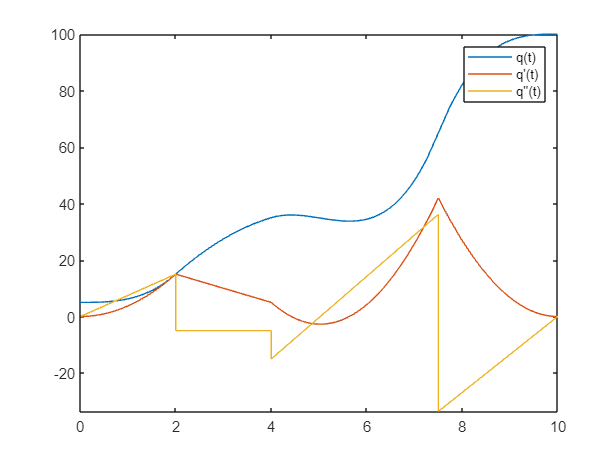

h(1) = fplot(q,[0,10]);
hold on;
h(2) = fplot(diff(q(t),t),[0,10]);
h(3) = fplot(diff(diff(q(t),t),t),[0,10]);
legend(h, 'q(t)', "q'(t)", "q''(t)");
hold off;

## Problem 2

### Solution 2(a)

The path is comprised of two semicircular segments. The first segment is from point P1 = (1.5,0.5) to the point on the y-axis (0,0.5). This can be expressed as:


$$X_1(s) = 0.75\cos s + 0.75 \\
Y_1(s) = -0.75\sin s + 0.5$$


where $s\in \left\lbrack 0,\pi \right\rbrack$.

Similarly, the second segment of the path is:


$$X_2(s) = 0.75\cos (s-\pi) - 0.75 \\
Y_2(s) = 0.75\sin (s-\pi) + 0.5,$$


where $s\in \left\lbrack \pi ,2\pi \right\rbrack$.

Let's verify that the path is correct by plotting it:

syms X(s) Y(s)
X(s) = piecewise(0<= s <= pi, 0.75*cos(s)+.75,pi<= s<= 2*pi,.75*cos(s-pi)-.75)

$$X(s) = \left\{ \begin{array}{cl} \frac{3\,\cos\left(s\right)}{4}+\frac{3}{4} & \text{ if }s\in \left[0,\pi \right]\\ -\frac{3\,\cos\left(s\right)}{4}-\frac{3}{4} & \text{ if }s\in \left[\pi ,2\,\pi \right] \end{array}\right.$$

Y(s) = piecewise(0<= s <= pi, -0.75*sin(s)+.5,pi<= s<= 2*pi,.75*sin(s-pi)+.5)

$$Y(s) = \left\{ \begin{array}{cl} \frac{1}{2}-\frac{3\,\sin\left(s\right)}{4} & \text{ if }s\in \left[0,2\,\pi \right] \end{array}\right.$$

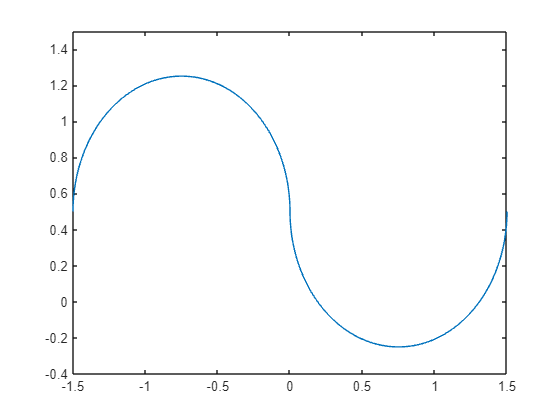

fplot(X,Y,[0,2*pi])
axis([-1.5 1.5 -0.4 1.5])

To convert it to a trajectory we need s(t). Let it be written as two line segments, i.e. 


$$s_1(t) = a_1t+a_0,$$


where $t\in[0,T/2]$ and $T$ is the total time of the trajectory. Since the two segments are identical and velocity is constant, one segment will require $T/2$ time. The second segment will be defined in exactly the same way. We have the constraints that $s_1(0) = 0$ and $s_1(T/2) = \pi$. So,


$$s_1(t) = \frac{2\pi}{T}t.$$


The second segment is $s_2(t) = a_1t+a_0,$ over $t\in[T/2,T]$. The constraints are that $s_2(T/2) = \pi$ and $s_2(T) = 2\pi$. The coefficients can be determined as:

syms a_1 a_0 t T;
s2(t) = a_1*t+a_0;
coeff = solve({s2(T/2)==pi, s2(T)==2*pi},[a_0, a_1]);
s2(t) = subs(s2(t),[a_0,a_1],[coeff.a_0,coeff.a_1])

$$s2(t) = \frac{2\,\pi \,t}{T}$$

Thus,

$s(t) = \frac{2\pi}{T}t$, for $t\in[0,T]$.

The final constraint is that the velocity of trajectory should be 1, i.e. 


$$\sqrt{\dot{X}^2(t)+\dot{Y}^2(t)} = 1, \qquad\forall t\in[0,T].$$


We have that 


$$X(t) = \left\lbrace \begin{array}{cl}
\frac{3}{4}\left[1+\cos \left(\frac{2\pi t}{T}\right)\right] & \;\textrm{if}\;\;t\in \left\lbrack 0,T/2 \right\rbrack \\
-\frac{3}{4}\left[1+\cos \left(\frac{2\pi t}{T}\right)\right] & \;\textrm{if}\;\;t\in \left\lbrack T/2 ,T \right\rbrack 
\end{array}\right.$$


and 

$Y(t) = \frac{1}{2}-\frac{3}{4}\sin\left(\frac{2\pi t}{T}\right), \quad \forall t\in[0,T]$.

Correspondingly,


$$\dot{X}(t) = \left\lbrace \begin{array}{cl}
-\frac{3\pi}{2T}\,\sin \left(\frac{2\pi t}{T}\right) & \;\textrm{if}\;\;t\in \left\lbrack 0,T/2 \right\rbrack \\
\frac{3\pi}{2T}\,\sin \left(\frac{2\pi t}{T}\right) & \;\textrm{if}\;\;t\in \left\lbrack T/2 ,T \right\rbrack 
\end{array}\right.$$


and 

$\dot{Y}(t) = -\frac{3\pi}{2T}\cos\left(\frac{2\pi t}{T}\right), \quad \forall t\in[0,T]$.

Thus,


$$\sqrt{\dot{X}^2(t)+\dot{Y}^2(t)} = \frac{3\pi}{2T} = 1 \quad\Rightarrow\quad T = \frac{3\pi}{2}.$$


The final trajectory is:


$$X(t) = \left\lbrace \begin{array}{cl}
\frac{3}{4}\left[1+\cos \left(\frac{4 t}{3}\right)\right] & \;\textrm{if}\;\;t\in \left\lbrack 0,3\pi/4 \right\rbrack \\
-\frac{3}{4}\left[1+\cos \left(\frac{4 t}{3}\right)\right] & \;\textrm{if}\;\;t\in \left\lbrack 3\pi/4 ,3\pi/2 \right\rbrack 
\end{array}\right.$$


$Y(t) = \frac{1}{2}-\frac{3}{4}\sin\left(\frac{4 t}{3}\right), \quad \forall t\in[0,3\pi/2]$.

syms t X(t) Y(t);
Y(t) = 1/2-3/4*sin(4*t/3);
X(t) = piecewise(0<=t<=3*pi/4,3/4+3/4*cos(4*t/3), 3*pi/4<=t<=3*pi/2,-3/4-3/4*cos(4*t/3));

### Solution 2(b)

T has already been found in (a).

### Solution 2(c )

We know closed-form solution for IK of this manipulator from the slides. The elbow-down solution is


$$\theta_1(t) = \arctan2(Y(t),X(t))-\arccos \left(\frac{l_1^2+X^2+Y^2-l_2^2}{2l_1\sqrt{X^2+Y^2}}\right) \\
\theta_2(t) = \pi-\arccos \left(\frac{l_1^2+l_2^2-X^2-Y^2}{2l_1l_2}\right).$$


The elbow-up solution is:


$$\theta_1(t) = \arctan2(Y(t),X(t))+\arccos \left(\frac{l_1^2+X^2+Y^2-l_2^2}{2l_1\sqrt{X^2+Y^2}}\right) \\
\theta_2(t) = -\pi+\arccos \left(\frac{l_1^2+l_2^2-X^2-Y^2}{2l_1l_2}\right).$$


Let's try to use the elbow-down solution. Substituting $X(t), Y(t)$ from the previous part in this expression:

syms t theta_1(t) theta_2(t)
l1 = 1;
l2 = 1;
theta_1(t) = atan2(Y(t),X(t)) - acos((l1^2+X(t)^2+Y(t)^2-l2^2)/(2*l1*sqrt(X(t)^2+Y(t)^2)))

$$theta\_1(t) = \begin{array}{l} \left\{ \begin{array}{cl} -\sigma_{2}+\text{angle}\left(\sigma_{3}-\sigma_{1}+\frac{3}{4}+\frac{1}{2}\,\mathrm{i}\right) & \text{ if }t\in \left[0,\frac{3\,\pi }{4}\right]\\ -\sigma_{2}+\text{angle}\left(-\sigma_{3}-\sigma_{1}-\frac{3}{4}+\frac{1}{2}\,\mathrm{i}\right) & \text{ if }t\in \left[\frac{3\,\pi }{4},\frac{3\,\pi }{2}\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(\frac{4\,t}{3}\right)\,\mathrm{i}}{4}\\ \sigma_{2}=\mathrm{acos}\left(\frac{\sqrt{{\left(\sigma_{3}+\frac{3}{4}\right)}^{2}+{\left(\frac{3\,\sin\left(\frac{4\,t}{3}\right)}{4}-\frac{1}{2}\right)}^{2}}}{2}\right)\\ \sigma_{3}=\frac{3\,\cos\left(\frac{4\,t}{3}\right)}{4} \end{array}$$

theta_2(t) = pi-acos((l1^2+l2^2-X(t)^2-Y(t)^2)/(2*l1*l2))

$$theta\_2(t) = \left\{ \begin{array}{cl} \pi -\mathrm{acos}\left(1-\frac{{\left(\frac{3\,\sin\left(\frac{4\,t}{3}\right)}{4}-\frac{1}{2}\right)}^{2}}{2}-\frac{{\left(\frac{3\,\cos\left(\frac{4\,t}{3}\right)}{4}+\frac{3}{4}\right)}^{2}}{2}\right) & \text{ if }t\in \left[0,\frac{3\,\pi }{2}\right] \end{array}\right.$$

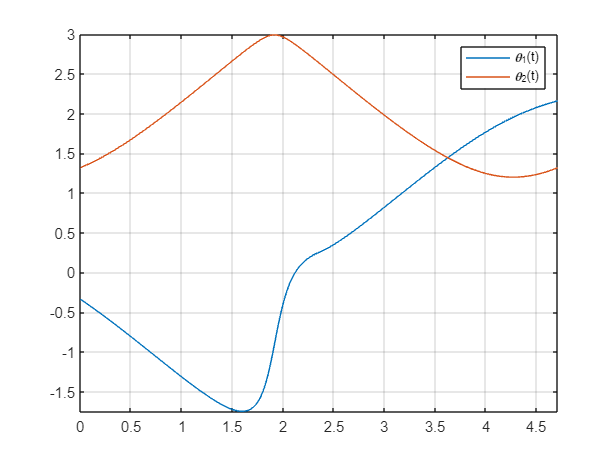

clear h;
h(1) = fplot(theta_1,[0,3*pi/2]);
hold on;
h(2) = fplot(theta_2,[0,3*pi/2]);
xlim([0.00 4.71]);
ylim([-1.75 3.00]);
grid on;
legend(h,'\theta_1(t)','\theta_2(t)');

#### Animation for the manipulator tracing the trajectory

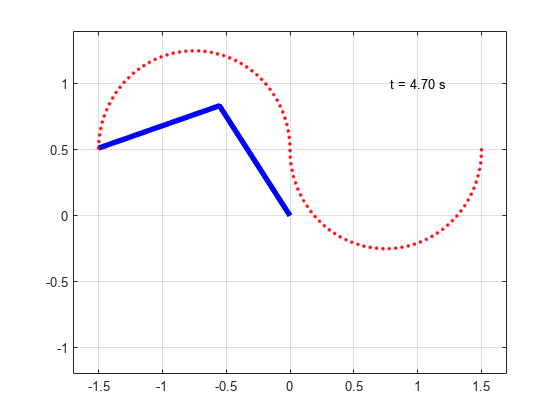

ti = 0:0.05:3*pi/2;
x1 = l1*cos(theta_1(ti));
x2 = x1+l2*cos(theta_1(ti)+theta_2(ti));
y1 = l1*sin(theta_1(ti));
y2 = y1+l2*sin(theta_1(ti)+theta_2(ti));

for i = 1:length(ti)
    if i == 1
        figure;
        % Plot the manipulator at its current configuration and store its
        % handle.
        hrobot = plot([0 x1(i) x2(i)], [0 y1(i) y2(i)], 'LineWidth',4, 'Color', 'blue');
        % Plot the tip of the robot and store the handle.
        hold on;
        htip = plot(x2(i),y2(i),'r.');
        hold off;
        % Turn on the grid and box
        grid on;
        box on;
        % Set axis limits
        axis([-1.7 1.7 -1.2 1.4])
        % Put text on the plot to show how much time has elapsed.  The text
        % is centered.
        htime = text(1,1,1,sprintf('t = %.2f s',ti(i)),'horizontalAlignment','center');
    else
        set(hrobot,'xdata',[0 x1(i) x2(i)],'ydata',[0 y1(i) y2(i)]);
        set(htip,'xdata',x2(1:i),'ydata',y2(1:i))
        set(htime,'string', (sprintf('t = %.2f s',ti(i))));
    end
    pause(0.1);
end

### Solution 2(d)

Let's differentiate $\theta_1(t)$ and $\theta_2(t)$ to obtain the joint angular velocities:

syms w1(t) w2(t)
w1(t) = simplify(expand(diff(theta_1(t),t)))

$$w1(t) = \begin{array}{l} \left\{ \begin{array}{cl} -\frac{2\,\sqrt{3}\,\left(22\,\sigma_{8}+33\,\sigma_{9}+\sigma_{1}+36\,{\sigma_{8}}^{2}+\sigma_{5}+\sigma_{3}-\sigma_{2}-18\right)}{\sigma_{4}} & \text{ if }t\in \left(0,\frac{3\,\pi }{4}\right)\\ -\frac{2\,\sqrt{3}\,\left(22\,\sigma_{8}+33\,\sigma_{9}+\sigma_{1}+36\,{\sigma_{8}}^{2}-\sigma_{5}-\sigma_{3}+\sigma_{2}-18\right)}{\sigma_{4}} & \text{ if }t\in \left(\frac{3\,\pi }{4},\frac{3\,\pi }{2}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{15\,\sin\left(\frac{8\,t}{3}\right)}{2}\\ \sigma_{2}=2\,\sqrt{3}\,\sigma_{9}\,\sigma_{6}\,\sigma_{7}\\ \sigma_{3}=3\,\sqrt{3}\,\sigma_{8}\,\sigma_{6}\,\sigma_{7}\\ \sigma_{4}=3\,\sigma_{6}\,{\left(9\,\sigma_{8}-6\,\sigma_{9}+11\right)}^{3/2}\\ \sigma_{5}=3\,\sqrt{3}\,\sigma_{6}\,\sigma_{7}\\ \sigma_{6}=\sqrt{2\,\sigma_{9}-3\,\sigma_{8}+7}\\ \sigma_{7}=\sqrt{9\,\sigma_{8}-6\,\sigma_{9}+11}\\ \sigma_{8}=\cos\left(\frac{4\,t}{3}\right)\\ \sigma_{9}=\sin\left(\frac{4\,t}{3}\right) \end{array}$$

w2(t) = simplify(diff(theta_2(t),t))

$$w2(t) = \left\{ \begin{array}{cl} \frac{4\,\sqrt{13}\,\sin\left(\frac{4\,t}{3}+\mathrm{atan}\left(\frac{2}{3}\right)\right)}{\sqrt{256-{\left(6\,\sin\left(\frac{4\,t}{3}\right)-9\,\cos\left(\frac{4\,t}{3}\right)+5\right)}^{2}}} & \text{ if }t\in \left(0,\frac{3\,\pi }{2}\right) \end{array}\right.$$

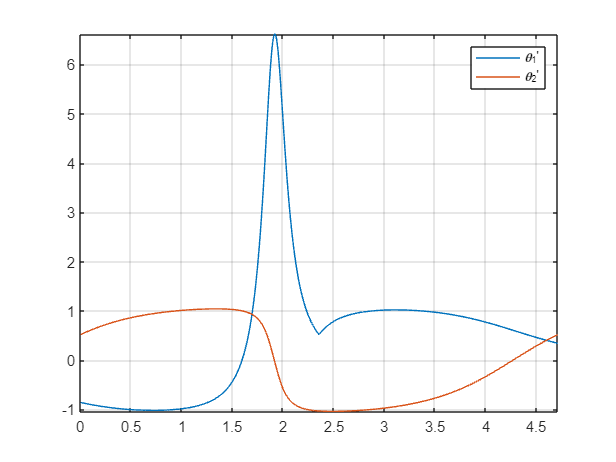

clear h;
figure;
h(1) = fplot(w1,[0,3*pi/2]);
hold on;
h(2) = fplot(w2,[0,3*pi/2]);
grid on;
hl = legend(h,"\theta_1'","\theta_2'");

We can see from the speed plot that of joint 1 that there is a spike. This spike happens at the time when the manipulator is switching from elbow-down to elbow-up solution. If the actuator limits don't allow this speed then the trajectory's speed will have to be reduced. We can determine the value and position of the maximum from the plot:

### Solution 2(e)

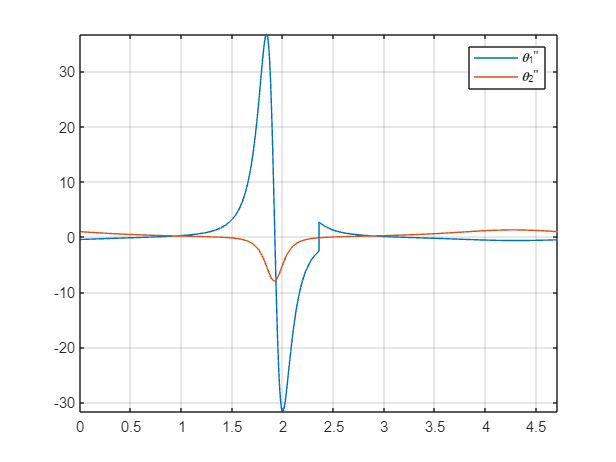

syms a1(t) a2(t)
a1(t) = diff(w1(t),t);
a2(t) = diff(w2(t),t);
clear h;
figure;
h(1) = fplot(a1,[0,3*pi/2]);
hold on;
h(2) = fplot(a2,[0,3*pi/2]);
grid on;
hl = legend(h,"\theta_1''","\theta_2''");

## Problem 3

### Solution (a)

The general model of a manipulator as provided in the slides is:


$$J(q)\,\ddot{q}+C(q,\dot{q})\,\dot{q}+B_v\,\dot{q}+g(q) = \tau.$$


For the 2R manipulator, the mass-matrix, coriollis matrix, and gravity terms are:


$$J(q) = \pmatrix{m_1l_1^2+m_2(l_1^2+2l_1l_2\cos q_2+l_2^2) & m_2(l_1l_2\cos q_2 + l_2^2) \cr
m_2(l_1l_2\cos q_2+l_2^2) & m_2l_2^2} \\
C(q,\dot{q}) = \pmatrix{-2m_2l_1l_2\sin q_2\;\dot{q}_2 & \dot{q}_2 \cr
m_2l_1l_2\sin q_2\; \dot{q}_1 & 0} \\
g(q) = \pmatrix{(m_1+m_2)l_1g\cos q_1+m_2gl_2\cos(q_1+q_2)\cr
m_2ga_2\cos(q_1+q_2)}$$


Let's create these matrices numerically with the provided parameter values. Since the friction values are not provided, let's ignore those terms.

m1=1;
m2=1;
l1=1;
l2=1;
g=9.8;
J(t) = [m1*l1^2+m2*(l1^2+2*l1*l2*cos(theta_2(t))+l2^2), m2*(l1*l2*cos(theta_2(t))+l2^2);
    m2*(l1*l2*cos(theta_2(t))+l2^2), m2*l2^2];
C(t) = [-2*m2*l1*l2*sin(theta_2(t))*w2(t), w2(t);
    m2*l1*l2*sin(theta_2(t))*w1(t),  0];
G(t) = [(m1+m2)*l1*g*cos(theta_1(t))+m2*g*l2*cos(theta_1(t)+theta_2(t));
    m2*g*l2*cos(theta_1(t)+theta_2(t))];

So the required torque by each joint to execute our desired trajectory, as a function of time, is computed below:

tau(t) = simplify(J(t)*[a1(t);a2(t)]+C(t)*[w1(t);w2(t)]+G(t))

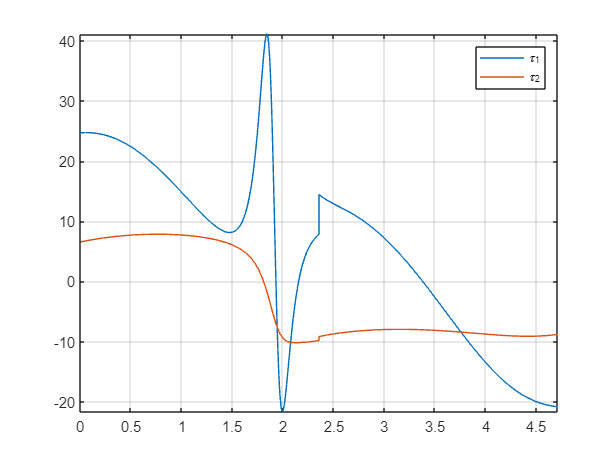

torque = tau(t);
clear h;
figure;
h(1) = fplot(torque(1),[0,3*pi/2]);
hold on;
h(2) = fplot(torque(2),[0,3*pi/2]);
grid on;
hl = legend(h,"\tau_1","\tau_2");

### Solution 3(b)

We'll use ode45 to simulate the system. Our state will be 


$$q(t) = \pmatrix{ \theta_1(t) \cr \theta_2(t) \cr \dot{\theta}_1(t)\cr \dot{\theta}_2(t)}$$


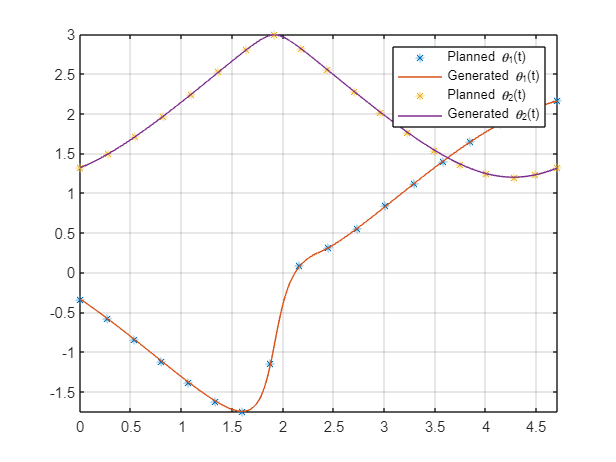

% Define initial conditions and time span
syms t;
clear q;
tspan = [1e-12 3*pi/2-1e-12];
q0 = double([theta_1(0); theta_2(0); limit(w1,t,0,'right'); limit(w2,t,0,'right')]);
% Define ODE function 
dqdt = @(ti,q) ([q(3); q(4); 
    2*m2*l1*l2*sin(q(2))*q(4)*q(3)-q(4)^2-(m1+m2)*l1*g*cos(q(1))-m2*g*l2*cos(q(1)+q(2));
    -m2*l1*l2*sin(q(2))*q(3)^2-m2*g*l2*cos(q(1)+q(2))]+[0;0;double(subs(torque(1),t,ti));double(subs(torque(2),t,ti))]);

% Define the mass matrix
M = @(ti,q)[1 0 0 0; 0 1 0 0; 0 0 m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2) m2*(l1*l2*cos(q(2))+l2^2);  0 0 m2*(l1*l2*cos(q(2))+l2^2) m2*l2^2];
% Set the mass-matrix option of ode
options = odeset('Mass',M,'RelTol', 1e-10, 'AbsTol', 1e-12);
% Solve the ODE
[ti,q] = ode45(dqdt, tspan, q0,options);

% Plotting and comparing the results to the ones obtained earlier
figure;
clear h;
h(1) = fplot(theta_1,[0,3*pi/2],'*');
hold on;
h(2) = plot(ti,q(:,1));
h(3) = fplot(theta_2,[0,3*pi/2],'*');
h(4) = plot(ti,q(:,2));

xlim([0.00 4.71]);
ylim([-1.75 3.00]);
grid on;
legend(h,'Planned \theta_1(t)','Generated \theta_1(t)','Planned \theta_2(t)', 'Generated \theta_2(t)');

### Solution 3(c)

Let's increase the masses by 10%:

m1 = 1.1;
m2 = 1.1;

Now let's simulate the system again:

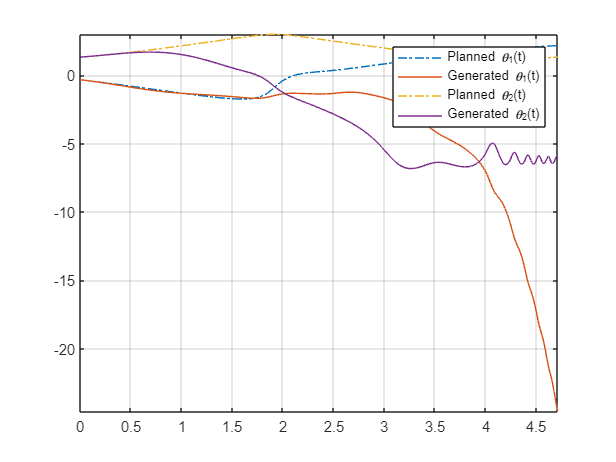

% Define ODE function 
dqdt = @(ti,q) ([q(3); q(4); 
    2*m2*l1*l2*sin(q(2))*q(4)*q(3)-q(4)^2-(m1+m2)*l1*g*cos(q(1))-m2*g*l2*cos(q(1)+q(2));
    -m2*l1*l2*sin(q(2))*q(3)^2-m2*g*l2*cos(q(1)+q(2))]+[0;0;double(subs(torque(1),t,ti));double(subs(torque(2),t,ti))]);

% Define the mass matrix
M = @(ti,q)[1 0 0 0; 0 1 0 0; 0 0 m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2) m2*(l1*l2*cos(q(2))+l2^2);  0 0 m2*(l1*l2*cos(q(2))+l2^2) m2*l2^2];
% Set the mass-matrix option of ode
options = odeset('Mass',M);
% Solve the ODE
[ti,q] = ode45(dqdt, tspan, q0,options);

% Plotting and comparing the results to the ones obtained earlier
figure;
clear h;
h(1) = fplot(theta_1,[0,3*pi/2],'-.');
hold on;
h(2) = plot(ti,q(:,1));
h(3) = fplot(theta_2,[0,3*pi/2],'-.');
h(4) = plot(ti,q(:,2));
grid on;
legend(h,'Planned \theta_1(t)','Generated \theta_1(t)','Planned \theta_2(t)', 'Generated \theta_2(t)');

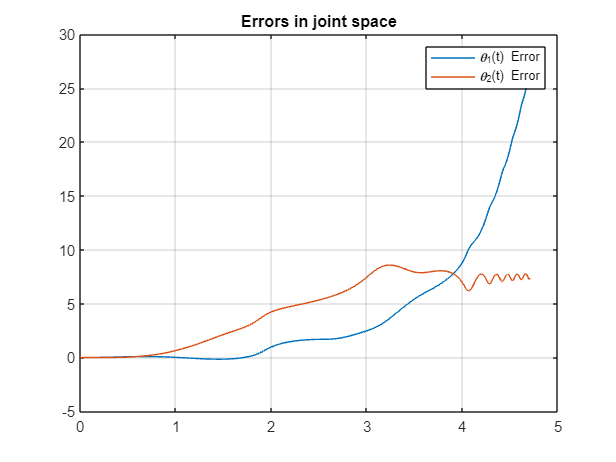

% Error in joint space
q1_error = double(theta_1(ti))-q(:,1);
q2_error = double(theta_2(ti))-q(:,2);
figure;
clear h;
h(1) = plot(ti,q1_error);
hold on;
h(2) = plot(ti,q2_error);
grid on;
legend(h,'\theta_1(t) Error','\theta_2(t) Error');
title('Errors in joint space');

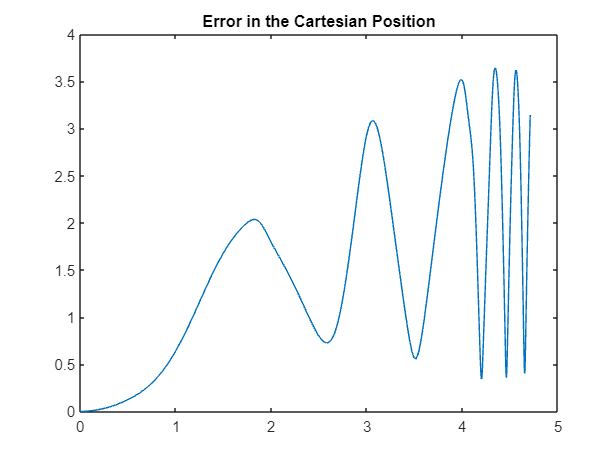

% Error in Cartesian Space
x_planned = double(l1*cos(theta_1(ti))+l2*cos(theta_1(ti)+theta_2(ti)));
y_planned = double(l1*sin(theta_1(ti))+l2*sin(theta_1(ti)+theta_2(ti)));
x_gen = l1*cos(q(:,1))+l2*cos(q(:,1)+q(:,2));
y_gen = l1*sin(q(:,1))+l2*sin(q(:,1)+q(:,2));
error_cart = sqrt((x_planned-x_gen).^2+(y_planned-y_gen).^2);

% Plotting
figure;
plot(ti,error_cart);
title('Error in the Cartesian Position');

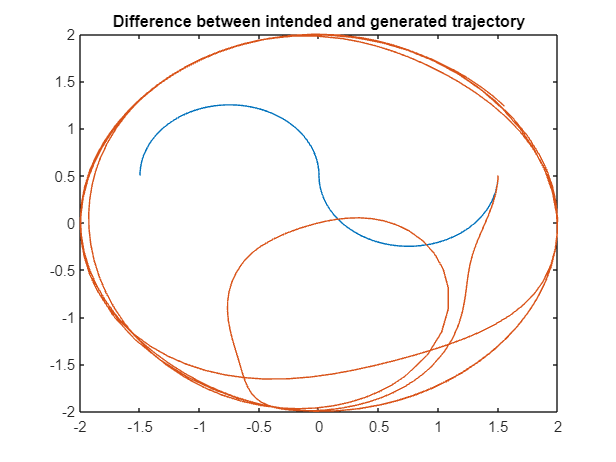

figure;
plot(x_planned,y_planned);
hold on;
plot(x_gen,y_gen);
title('Difference between intended and generated trajectory');

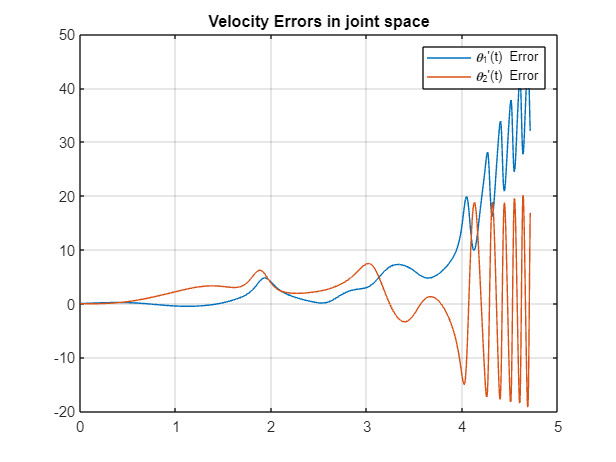

% Velocity error in the joint space
w1_error = double(w1(ti))-q(:,3);
w2_error = double(w2(ti))-q(:,4);
figure;
clear h;
h(1) = plot(ti,w1_error);
hold on;
h(2) = plot(ti,w2_error);
grid on;
legend(h,"\theta_1'(t) Error","\theta_2'(t) Error");
title('Velocity Errors in joint space');

### Solution 3(d)

Recall that for the computed torque controller we'll set our control, i.e. torque in this case as:


$$\tau = C(q,\dot{q})\,\dot{q}+g(q) + J(q)\,(\ddot{q}_d+\text{Feedback Controller)$$


The mass value that you'll be using for computing these terms will be 1kg, which is what you believe to be the mass. In reality, the mass is 10% higher and we'll see if the controller is able to compensate for that.

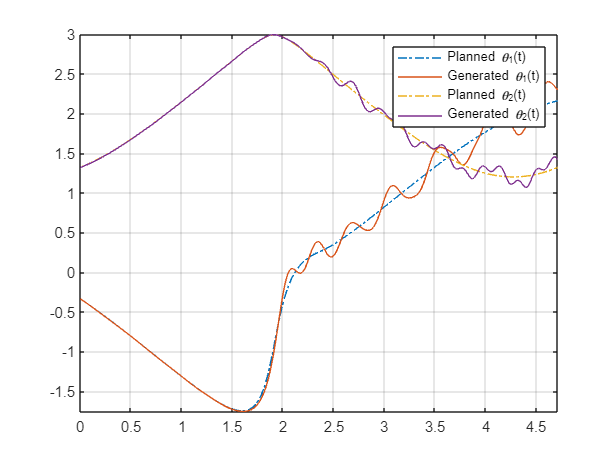

m1 = 1.1;
m2 = 1.1;
l1 = 1;
l2 = 1;
g = 9.8;

% Define ODE function 
dqdt = @(ti,q) ([q(3); q(4); 
    2*m2*l1*l2*sin(q(2))*q(4)*q(3)-q(4)^2-(m1+m2)*l1*g*cos(q(1))-m2*g*l2*cos(q(1)+q(2));
    -m2*l1*l2*sin(q(2))*q(3)^2-m2*g*l2*cos(q(1)+q(2))]+[0;0;controller(ti,q,theta_1, theta_2, a1, a2)]);

% Define the mass matrix
M = @(ti,q)[1 0 0 0; 0 1 0 0; 0 0 m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2) m2*(l1*l2*cos(q(2))+l2^2);  0 0 m2*(l1*l2*cos(q(2))+l2^2) m2*l2^2];
% Set the mass-matrix option of ode
options = odeset('Mass',M);
% Solve the ODE
[ti,q] = ode45(dqdt, tspan, q0,options);

% Plotting and comparing the results to the ones obtained earlier
figure;
clear h;
h(1) = fplot(theta_1,[0,3*pi/2],'-.');
hold on;
h(2) = plot(ti,q(:,1));
h(3) = fplot(theta_2,[0,3*pi/2],'-.');
h(4) = plot(ti,q(:,2));
grid on;
legend(h,'Planned \theta_1(t)','Generated \theta_1(t)','Planned \theta_2(t)', 'Generated \theta_2(t)');

function tau_computed = controller(t,q,theta_1, theta_2, a1, a2)
    m1 = 1;
    m2 = 1;
    l1 = 1;
    l2 = 1;
    g=9.8;
    persistent eint;
    persistent tprev;
    if isempty(eint)
        eint = [0;0];
        tprev = 0;
    end
    
    % This is compensating the corriolis and gravity terms
    tau_computed = [-2*m2*l1*l2*sin(q(2))*q(4)*q(3)+q(4)^2+(m1+m2)*l1*g*cos(q(1))+m2*g*l2*cos(q(1)+q(2));
                    m2*l1*l2*sin(q(2))*q(3)^2+m2*g*l2*cos(q(1)+q(2))];
    % Add the feedforward controller
    tau_computed = tau_computed + [m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2)*double(a1(t))+m2*(l1*l2*cos(q(2))+l2^2)*double(a2(t));  
                                   m2*(l1*l2*cos(q(2))+l2^2)*double(a1(t))+ m2*l2^2*double(a2(t))];
    % Add the feedback controller part
    Kp = 600;
    Ki = 100;
    e = [double(theta_1(t))-q(1); double(theta_2(t))-q(2)];
    dt = t-tprev;
    eint = eint + e*dt;
    tau_computed  = tau_computed + Kp*e + Ki*eint;
    tprev = t;
end